Importdata = readtable('heart_failure_clinical_records_dataset_neu.csv'); %Excel einlesen.
Rohdata = Importdata{:,1:12} %Eingelesene Excel (Tabelle) in Matrix übergeben.

Rohdata = 	1.0e+05 *

    0.0008         0    0.0058         0    0.0002    0.0000    2.6500    0.0000    0.0013    0.0000         0    0.0000
    0.0006         0    0.0786         0    0.0004         0    2.6336    0.0000    0.0014    0.0000         0    0.0001
    0.0006         0    0.0015         0    0.0002         0    1.6200    0.0000    0.0013    0.0000    0.0000    0.0001
    0.0005    0.0000    0.0011         0    0.0002         0    2.1000    0.0000    0.0014    0.0000         0    0.0001
    0.0006    0.0000    0.0016    0.0000    0.0002         0    3.2700    0.0000    0.0012         0         0    0.0001
    0.0009    0.0000    0.0005         0    0.0004    0.0000    2.0400    0.0000    0.0013    0.0000    0.0000    0.0001
    0.0008    0.0000    0.0025         0    0.0001         0    1.2700    0.0000    0.0014    0.0000         0    0.0001
    0.0006    0.0000    0.0032    0.0000    0.0006         0    4.5400    0.0000    0.0013    0.0000    0.0000    0.0001
    0.0006

Zdata = zscore(Rohdata)    %Alle Werte standardisieren.

Zdata =     1.1909   -0.8696    0.0002   -0.8462   -1.5280    1.3570    0.0168    0.4892   -1.5015    0.7345   -0.6865   -1.6268
   -0.4905   -0.8696    7.5021   -0.8462   -0.0071   -0.7345    0.0000   -0.2841   -0.1417    0.7345   -0.6865   -1.6010
    0.3502   -0.8696   -0.4492   -0.8462   -1.5280   -0.7345   -1.0363   -0.0907   -1.7281    0.7345    1.4517   -1.5881
   -0.9108    1.1460   -0.4853   -0.8462   -1.5280   -0.7345   -0.5456    0.4892    0.0849    0.7345   -0.6865   -1.5881
    0.3502    1.1460   -0.4348    1.1779   -1.5280   -0.7345    0.6507    1.2625   -4.6743   -1.3570   -0.6865   -1.5752
    2.4520    1.1460   -0.5512   -0.8462    0.1619    1.3570   -0.6069    0.6826   -1.0483    0.7345    1.4517   -1.5752
    1.1909    1.1460   -0.3461   -0.8462   -1.9505   -0.7345   -1.3942   -0.1874    0.0849    0.7345   -0.6865   -1.5495
   -0.0701    1.1460   -0.2750    1.1779    1.8519   -0.7345    1.9492   -0.2841   -1.2749    0.7345    1.4517   -1.5495
    0.3502   -0.8696   -

labelp = Importdata{:,13}' %Gruppierung Death/No Death

labelp =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     1     1     1     1     1     0     1     1     0     1     1     1     1     1     1     1     1     1     0     1     1     1     1     0     1     1     1     1     0     1     1     1     1     1     1


%Matlab PCA Analyse.

[coeff,score,latent] = pca(Zdata)  %PCA Analyse

coeff =     0.0477    0.5042    0.2228    0.3422   -0.0507    0.0024   -0.2208    0.4959    0.5159    0.0687   -0.0928
   -0.2290    0.3763    0.1933   -0.4457    0.0559   -0.1416    0.4849    0.3621   -0.2270   -0.3575   -0.0321
    0.1633   -0.3806   -0.1376    0.3719   -0.4821    0.2222    0.2542    0.4053   -0.1364   -0.3529   -0.1324
   -0.2843   -0.1823   -0.4130   -0.0221    0.2924   -0.2000   -0.3658    0.5677   -0.3067    0.1957   -0.0299
   -0.2617   -0.0476    0.4458    0.2378   -0.2268   -0.4369   -0.4329   -0.1463   -0.2773   -0.3686    0.1003
   -0.1911    0.1534    0.2243    0.2919    0.3885    0.7065   -0.0827   -0.0365   -0.3653   -0.0999    0.0533
   -0.1698   -0.2760    0.0841    0.4626    0.5000   -0.3211    0.4695   -0.0054    0.2413   -0.0474    0.1995
    0.0361    0.4719   -0.2292    0.4161   -0.2175   -0.2268    0.2711   -0.1525   -0.4522    0.3877   -0.0073
   -0.0929   -0.3135    0.6010   -0.1091   -0.1826    0.0558    0.1492    0.2123   -0.1182    0.6339   -

score =     0.8683    1.4605   -1.0166    1.1542    0.5226    1.8157    0.0665   -0.2696    0.9693   -0.0869    0.8516
    1.8634   -3.4219   -1.2218    2.6417   -4.2547    1.5934    1.8450    2.1976   -0.3940   -2.6384    0.0342
    2.5177    0.8796   -1.2536   -0.5334    0.3871    0.2674   -0.4665   -0.7415    0.9331   -0.2249   -0.7128
    0.5747    0.6812   -0.5913   -1.6878   -0.4074    0.2089    1.5304   -0.3624   -0.0655    0.4604    0.7947
   -0.9668    2.3852   -4.2928    0.2304    1.1714   -0.8860    0.7380   -0.1472    0.8546   -1.7909   -0.5478
    1.1897    3.0103    1.1084    0.7081    0.7939    0.4285   -0.3709    0.6899    0.0146   -0.8865   -0.6101
    0.9280    1.6231   -0.2469   -1.6914   -0.7623    0.8555    0.7027    0.9059    1.2181    0.4894    0.3744
    0.0484   -0.2272    0.2572    0.4994    1.7143   -2.7509   -0.1384    0.6151   -0.5688   -1.8150    0.1060
   -1.3198   -0.1150    1.0569    0.7489   -1.3777   -1.1075   -1.0219   -1.3445    0.6569   -0.1249   -

latent =     1.6630
    1.3954
    1.2667
    1.0533
    1.0258
    0.9650
    0.8583
    0.8174
    0.7592
    0.6829



Evarf = (latent./sum(latent));   
Ergf = cumsum(Evarf)            %Kumulierte Anteile der Varianz

Ergf =     0.1512
    0.2780
    0.3932
    0.4889
    0.5822
    0.6699
    0.7479
    0.8223
    0.8913
    0.9534



%Grafische Darstellung der anteiligen Varianz
x=0:1/10:1

x =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


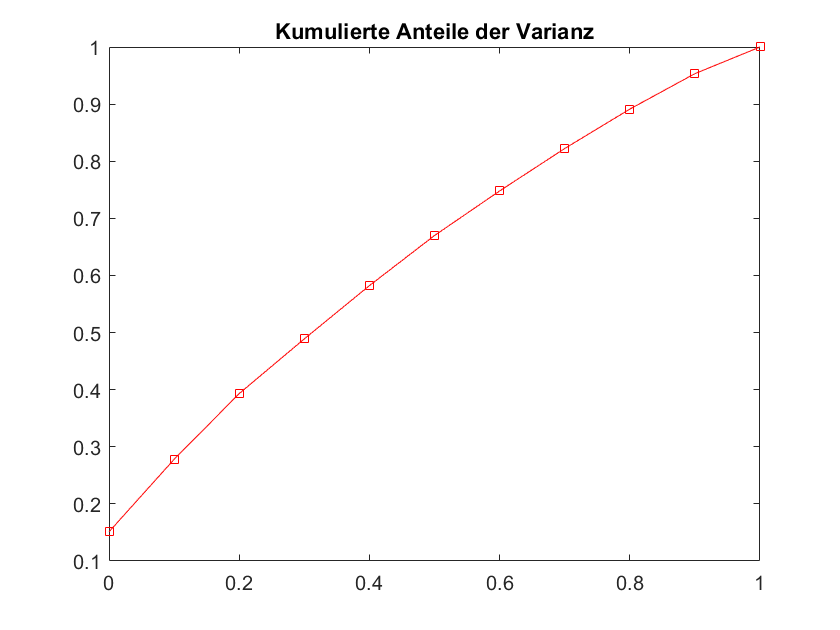

plot(x,Ergf,"-rs")
title('Kumulierte Anteile der Varianz')

%Clusteranalyse Rohdaten

Varlist = {'age','anaemia','creatinine phosphokinase','diabetes','ejection fraction','high blood pressure','platelets','serum creatinine','serum sodium','sex','smoking','time'};

for i=1:11,
    for j=i+1:12,
        figure
        gscatter(Rohdata(:,i),Rohdata(:,j),labelp,['g','r'])
        title('Cluster - 2 Input Features')
        legend('überlebt','tot')
        xlabel(Varlist(i))
        ylabel(Varlist(j))
   end
end

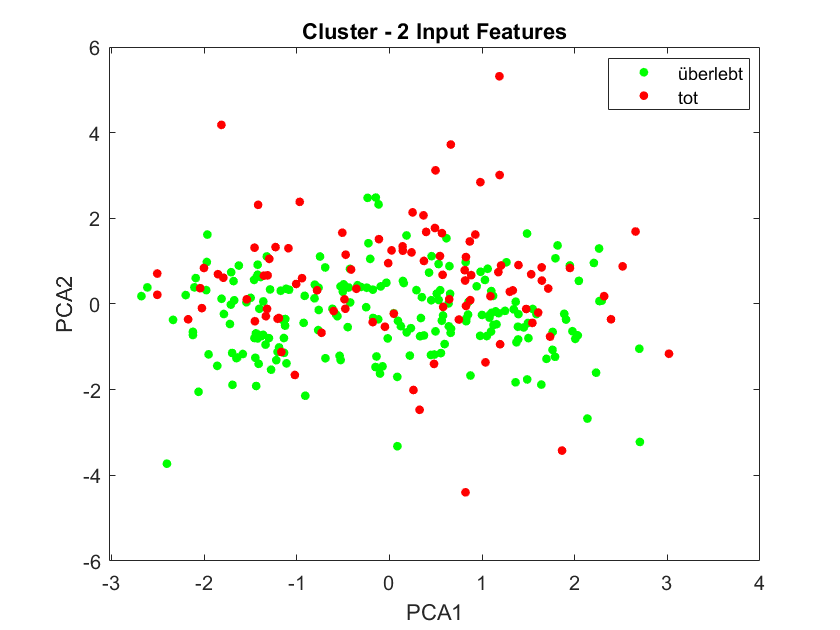

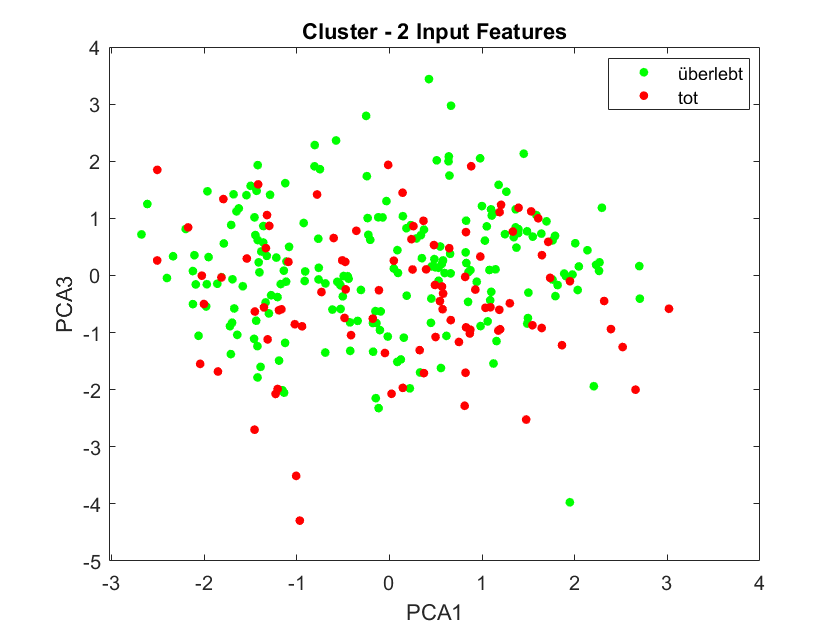

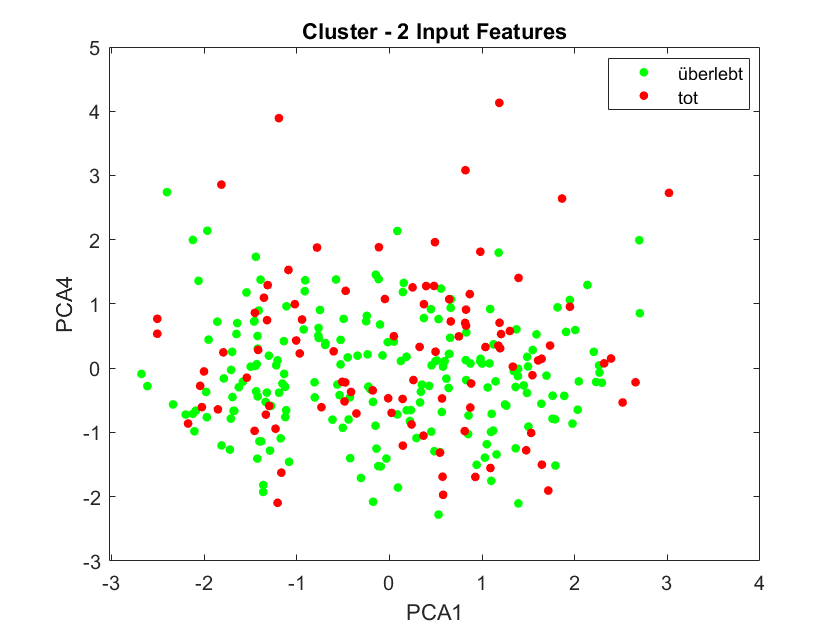

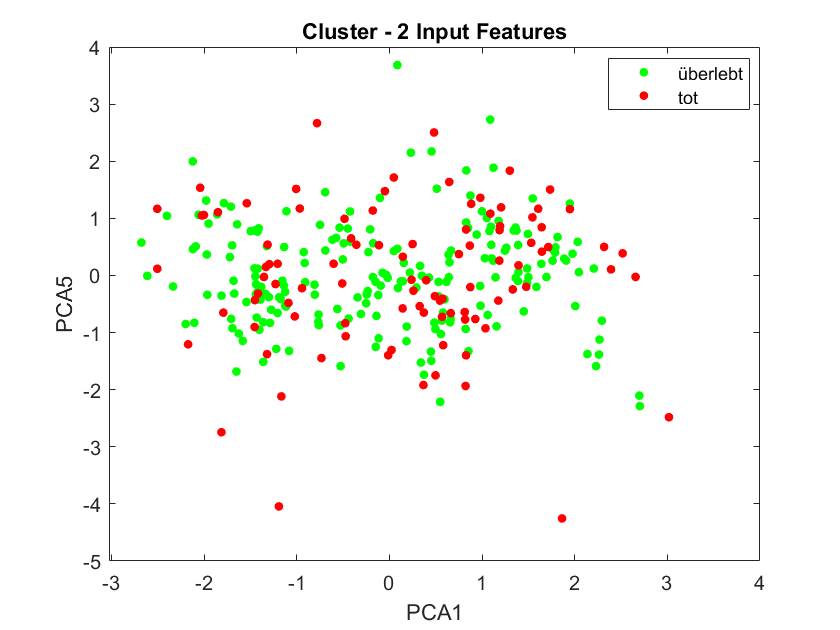

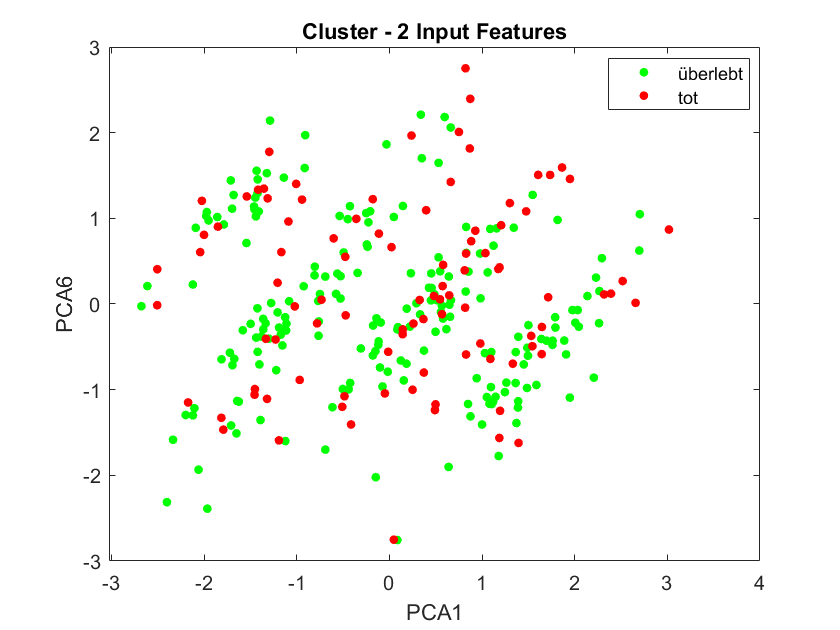

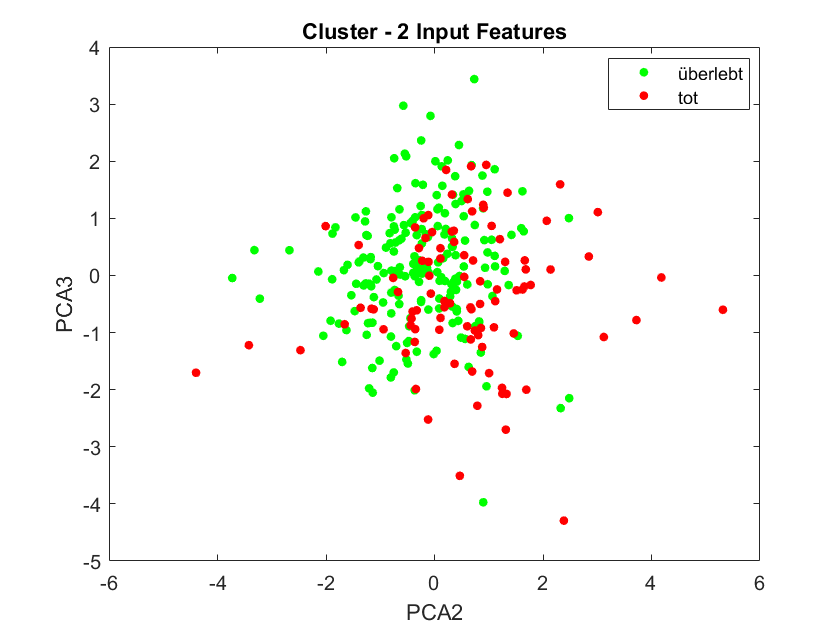

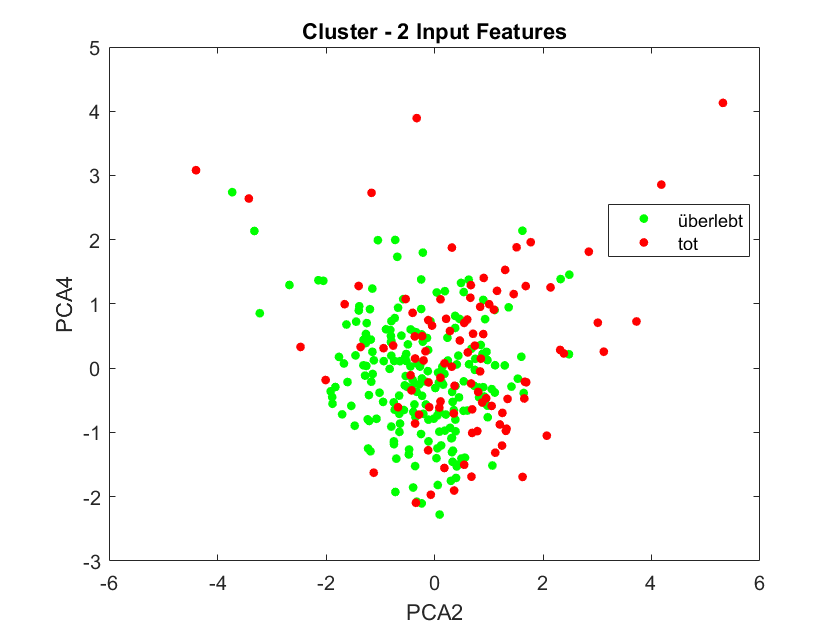

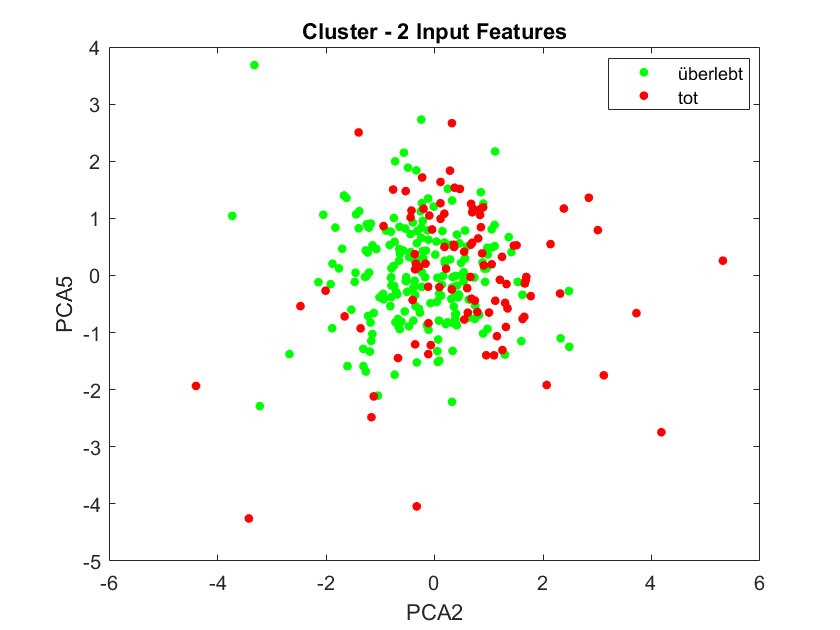

count = 67

%Clusteranalyse PCA Daten

Varlist = {'PCA1','PCA2','PCA3','PCA4','PCA5','PCA6','PCA7','PCA8','PCA9','PCA10','PCA11'};

for i=1:5,
    for j=i+1:6,
        figure
        gscatter(score(:,i),score(:,j),labelp,['g','r'])
        title('Cluster - 2 Input Features')
        legend('überlebt','tot')
        xlabel(Varlist(i))
        ylabel(Varlist(j))
    end
end